# Decomposition of HD-sEMG

Prof. Carina Marconi Germer

UNIVERSIDADE ESTADUAL DE CAMPINAS

## Mathmatical contextualization

In electromyography, the observations (i.e., the signals recorded) comprise the summation of the action potential trains of all motor units recruited. Each motor unit has a specific action potential shape per channel as it depends on its anatomical characteristics (e.g., size, type of innervated fibers and deepness), the volume conductor characteristics (e.g., tissues conductivities and thickness) and the recording system (e.g., electrode size, inter-electrode distance and recording mode). 

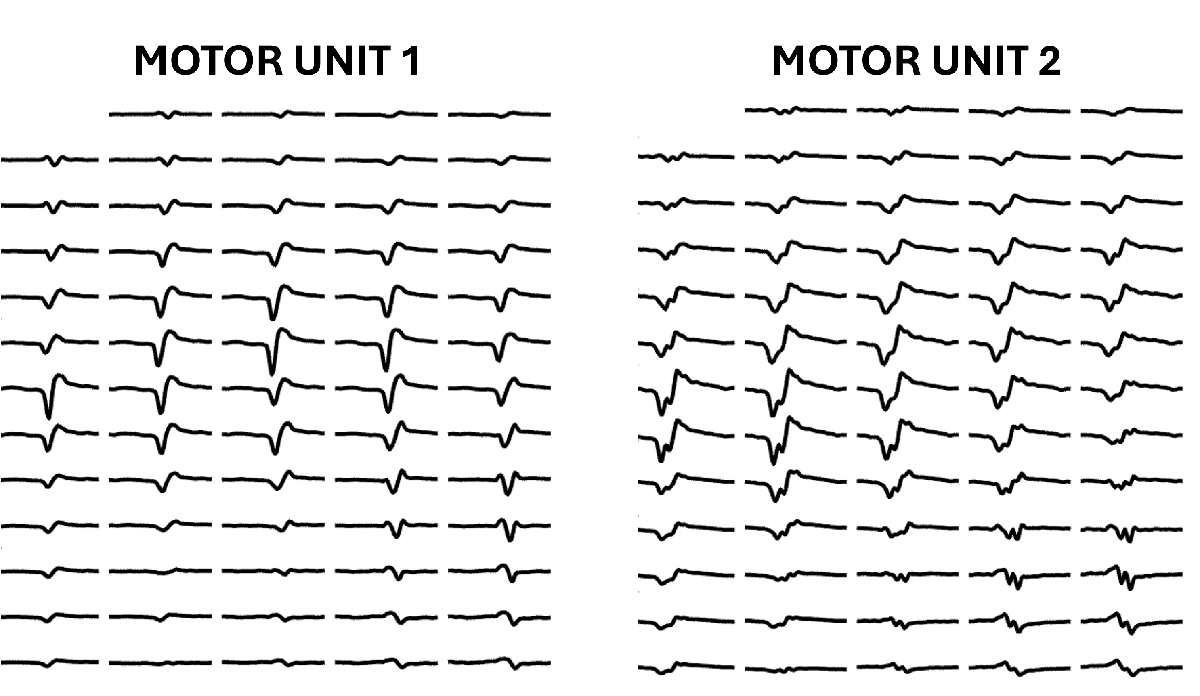

The problem is then usually modeled as instantaneous convolutive mixture, as it consists of the convolutional combination of action potential waveform and the discharge times. The model is said instantaneous because we assume the source signals arrive at the sensors at the same time. In this model, the sources are the discharge trains of motor units, and the mixing matrix comprises the filter from the action potential shapes at each electrode. We also assume the waveform is invariant in the time, which is true for isometric contractions. 

Assuming N active motor units are recorded by M electrodes, the signal on each channel can be described as:

                             $x_m {\left(t\right)}=\ \sum_{l=0}^{L-1} \sum_{n=1}^N a_{nm} {\left(l\right)}s_n {\left(t-l\right)}+\eta_m {\left(t\right)},\ \ \ \ \ m=1,\ldots,M;\ \ t=0,\ldots,D_R$              (1)

Where $x_m$ is the observation in the *m**th* channel at the time instant *t* (in the discrete time), $D_R$ is the duration of the recording (in samples), $a_{nm} {\left(l\right)}$ is the action potential waveform of the *n**th *motor unit in the* m**th* channel, *L *is the length of the action potential waveform, $s_n$ is the discharge train of the *n**th motor unit* modelled by a series of Dirac Delta function ($s_n {\left(t\right)}=\sum_k \delta \left(t-T_n {\left(k\right)}\right)$ , where $T_n$ are the discharge instants), and $\eta_m$ is the noise at channel *m. *Due to the refractory period, we can assume no overlapping of action potentials in the same motor unit, thus $T_n {\left(k+1\right)}-T_n {\left(k\right)}>L$  for $\forall k\in \mathbb{N}$. 

In the vector-matrix notation, Equation (1) becomes

           $\mathit{\mathbf{x}}{\left(t\right)}=\ \sum_{l=0}^{L-1} \mathit{\mathbf{A}}{\left(l\right)}\mathit{\mathbf{s}}{\left(t-l\right)}+\eta \left(t\right)$              (2)

Equation (2) is a finite impulse response (FIR) model, where $\mathit{\mathbf{x}}\left(t\right)={{\left[x_1 \left(t\right),x_2 \left(t\right),\ldots,\ x_M \left(t\right)\right]}}^T$  is the vector of observations,  $\mathit{\mathbf{A}}{\left(l\right)}={\left[{\mathit{\mathbf{a}}}_1 {\left(l\right)},\ldots,{\mathit{\mathbf{a}}}_{\mathit{\mathbf{N}}} {\left(l\right)}\right]}$ is the action potential filter of order L and size *M x N, *and $\mathit{\mathbf{s}}{\left(t\right)}={{\left[s_1 {\left(t\right)},\ldots,s_N {\left(t\right)}\right]}}^T$ is the vector of sources at time instant *t*. Superscript *T* denotes transposition of a vector or a matrix. 

The simplest approach to separate a convolutive instantaneous mixture is to represent it as a standard linear model by its compact form. First, the convolutive model is rewritten in its matrix form

 $\mathit{\mathbf{x}}{\left(t\right)}=\ \underline{\mathit{\mathbf{A}}\mathit{\mathbf{s}}} {\left(t\right)}+\eta \left(t\right)\in {\mathbb{R}}^{M\mathrm{x}1}$             (3)

Where $\underline{\mathit{\mathbf{A}}} ={\left[\mathit{\mathbf{A}}{\left(0\right)},\mathit{\mathbf{A}}{\left(1\right)},\ldots,\mathit{\mathbf{A}}{\left(L-1\right)}\right]}\in {\mathbb{R}}^{M\mathrm{x}NL}$ , and $\underline{\mathit{\mathbf{s}}} \left(\mathit{\mathbf{t}}\right)={{\left[{\mathit{\mathbf{s}}}^T {\left(t\right)},{\mathit{\mathbf{s}}}^T {\left(t-1\right)},\ldots,{\mathit{\mathbf{s}}}^T {\left(t-L+1\right)}\right]}}^T \in {\mathbb{R}}^{NL\mathrm{x}1}$ contains the latest L samples of the sources. 

By using a sliding window of length K+1, here after referred to as the extension factor, it yields to a block-based model

                   $\overset{~}{\mathit{\mathbf{x}}} {\left(t\right)}=\overset{~}{\mathit{\mathbf{A}}} \overset{~}{\mathit{\mathbf{s}}} {\left(t\right)}+\overset{~}{\eta} \left(t\right)\in {\mathbb{R}}^{M{\left(K+1\right)}\mathrm{x}1}$     (4)

Where, $\overset{~}{\mathit{\mathbf{x}}} {\left(t\right)}={{\left[{\mathit{\mathbf{x}}}^{\mathit{\mathbf{T}}} {\left(t\right)},{\mathit{\mathbf{x}}}^{\mathit{\mathbf{T}}} {\left(t-1\right)},\ldots,{\mathit{\mathbf{x}}}^{\mathit{\mathbf{T}}} {\left(t-K\right)}\right]}}^T$, is the extended vector of observations containing the original signals and K delayed versions, and

$\overset{~}{\mathit{\mathbf{A}}} ={\left[\begin{array}{ccccccc}
\mathit{\mathbf{A}}\left(0\right) & \mathit{\mathbf{A}}\left(1\right) & \ldots & \mathit{\mathbf{A}}\left(L-1\right) & 0 & \ldots & 0\\
0 & \mathit{\mathbf{A}}\left(0\right) & \ldots & \mathit{\mathbf{A}}\left(L-2\right) & \mathit{\mathbf{A}}\left(L-1\right) & \ldots & 0\\
\vdots  & \ddots  & \ddots  & \ddots  & \ddots  & \ddots  & \vdots \\
0 & \ldots & 0 & \mathit{\mathbf{A}}\left(0\right) & \ldots & \mathit{\mathbf{A}}\left(L-2\right) & \mathit{\mathbf{A}}\left(L-1\right)
\end{array}\right]}\in {\mathbb{R}}^{M{\left(K+1\right)}\mathrm{x}\mathrm{N}\left(\mathrm{L}+\mathrm{K}\right)}$ , 

 $\overset{~}{\mathit{\mathbf{s}}} {\left(t\right)}={{\left[{\mathit{\mathbf{s}}}^T {\left(t\right)},{\mathit{\mathbf{s}}}^T {\left(t-1\right)},\ldots,{\mathit{\mathbf{s}}}^T \left(t-L-K+1\right)\right]}}^T \in {\mathbb{R}}^{N{\left(L+K\right)}\mathrm{x}1}$, and

  
$$\overset{~}{\eta} {\left(t\right)}={{\left[\eta^T {\left(t\right)},\eta^T {\left(t-1\right)},\ldots,\eta^T \left(t-K\right)\right]}}^T \in {\mathbb{R}}^{N{\left(L+K\right)}\mathrm{x}1}$$


The mixing matrix $\overset{~}{\mathit{\mathbf{A}}}$ is a generalized Sylvester block Toeplitz matrix, having  $K+1$ vertical and $L+K$  horizontal  $M\mathrm{x}N$ blocks, and is full column rank. 

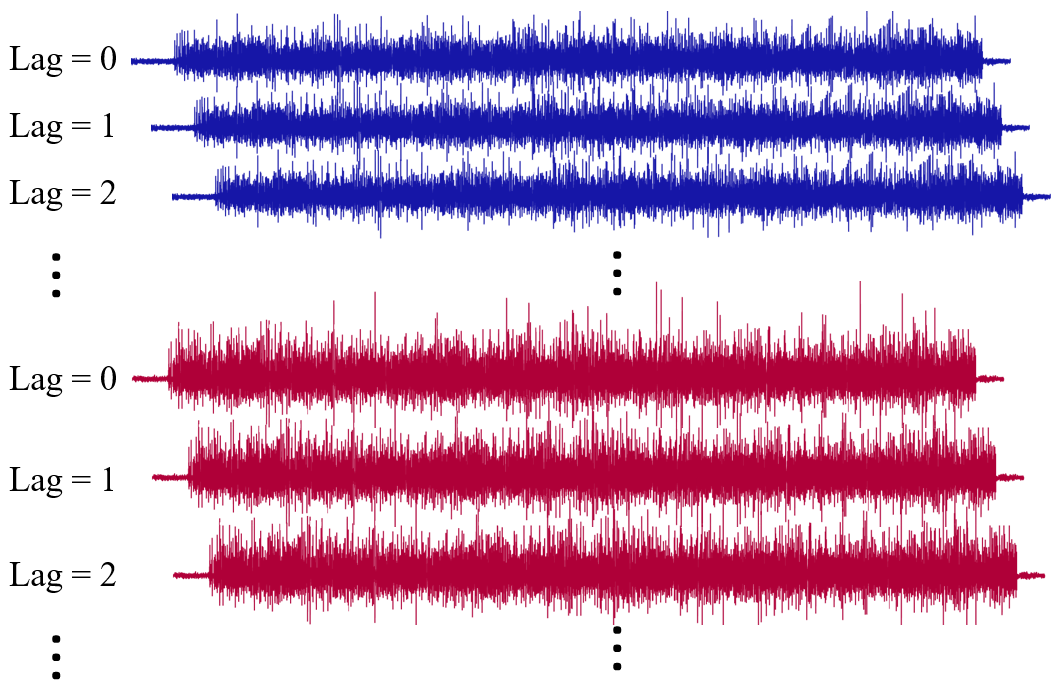

Equation 4 models the mixture system and the demixing system is fiven by Equation 5

                                  $\hat{s} \left(t\right)=\overset{~}{\mathit{\mathbf{D}}} \overset{~}{\mathit{\mathbf{x}}} {\left(t\right)}$           (5)

 Where $\overset{~}{\mathit{\mathbf{D}}} \mathit{\mathbf{\ }}\in {\mathbb{R}}^{N{\left(L+K\right)}\mathrm{x}M{\left(K+1\right)}}$ is the matrix of coefficients of the separating system filters, also called matrix of weights, and $\widehat{s} \left(t\right)$  is the estimated source vector. The demixing problem builds on the fundamental assumption of statistical independence or sparseness (non-Gaussianity) of the sources. The model also assumes that the source signal vector are zero-mean stationary real signals and is independent of the noise vector. To make the zero-mean assumption hold we center the observation matrix by subtracting their sample mean. Moreover, the extension factor (K+1) should be large enough to assure   to yield to an overdetermined multiple-input multiple-output demixing model. 

Once the convolutive mixture model (Equation 1) is approximated to an instantaneous linear mixture model (Equation 5), we can proceed to the separation problem by standard linear independent component analysis. The approach chosen was fastICA.

## Decomposition of HD-sEMG

Use the program below to explore some of the decomposition parameters and answare the folowing questions:

**Questions:**

- Why is it important to remove "bad channels" or trim the data before processing?

- How does whitening impact the decomposition process?

- How does the extension factor influence the processing and results of the decomposition?

- How do different contrast functions affect the quality of the decomposition in terms of pulse-to-noise ratio, convergence time, and consistency in identifying motor units?

- Is there a preferred contrast function for decomposition? If so, why?

- Why does the code converge to the same source even after applying orthogonalization?

- What do the estimated sources represent in the context of the decomposition?

- Are there any additional steps required after performing FastICA?

- How critical is the "initialization strategy" for the success of the decomposition?

### Load Data

 
close all; clear, clc
currentFolder = pwd;
addpath(fullfile(pwd,'subfunctions'));
addpath(fullfile(pwd,'data'));

Example = "Steady_5MVC";

% load data
switch Example
    case 'Steady_5MVC'
        load EMG_AV_5_00_2.mat;
    case 'Steady_5MVC_2'
        load GC_5.mat;
    case 'Trapezoidal_15MVC'
        load C15_Ne_VF_S_01_EMG.mat;
end

fprintf('done!')

figure();

oSIG=SIG;

### Pre-process the Observations

#### Check signals

 
figure()
t=(1:length(SIG{2}))/fsamp;
for ch=1:numel(SIG)
    subplot(size(SIG,2),size(SIG,1),ch)
    if ~isempty(SIG{ch})
        plot(t,SIG{ch},'k');
    end
    set(gca,'XTick',[],'YTick',[]);
    title(sprintf('Ch%d',ch),'FontSize',6)
    box off
end


#### Undo Edition

 
SIG=oSIG;

#### Delete Channels and Cut Data

DeleteCh = false;
CutDataStart = 0;
CutDataEnd = 0;


if DeleteCh
    DeleteChannels = [9,10,11];
    for dch=1:length(DeleteChannels)
        SIG{DeleteChannels(dch)}=[];
    end
end

for ch=1:numel(SIG)
    if ~isempty(SIG{ch})
        SIG{ch}=SIG{ch}(CutDataStart*fsamp+1:end-CutDataEnd*fsamp);
    end
end

NSamples=max(cellfun(@length,SIG));
t=(1:NSamples)/fsamp;
figure()
for ch=1:numel(SIG)
    subplot(size(SIG,2),size(SIG,1),ch)
    if ~isempty(SIG{ch})
        plot(t,SIG{ch},'k');
    end
    set(gca,'XTick',[],'YTick',[]);
    title(sprintf('Ch%d',ch),'FontSize',6)
    box off
end

#### Extend and Whiten

 
extFact=12;
Whiten = true;

Data = cell2mat(reshape(SIG,[numel(SIG) 1]));

eYW = PreProcessObservations(Data,extFact,Whiten);

covmat = eYW*eYW' / (length(eYW)-1);

figure(),
subplot(1,2,1)
covmat = Data*Data' / (length(Data)-1);
imagesc(covmat)
title({'Covariance Matrix'; 'of Observations'})
axis square
box off
xlabel('Channels')
ylabel('Channels')


covmat = eYW*eYW' / (length(eYW)-1);
subplot(1,2,2)
imagesc(covmat)
title({'Covariance Matrix'; 'of Extended Observations'})
axis square
box off
xlabel('Channels')
% fprintf('done!')

### FastICA 

#### Initialize Separation Matrix

 

ii=0;
B = zeros(size(eYW,1),size(eYW,1));
ACT = sum(abs(eYW).^2,1);               %activity index

% figure()
% plot(t,ACT)
% xlim([0 t(end)])
% title('Activity Index')
% xlabel('Time (s)')
% ylabel('Amplitude (mV^2)')


fprintf('done!')

 

CF="G3";

[G,DG]=ContrastFunctions(CF);
MAXCOUNT = 20;        % max number of interations fixed point 
InitStrategy="max";
PLOTiBSS=1;

%%
ii=ii+1;

switch InitStrategy
    case 'max'
        [~,ind] = max(ACT);
    case '95%'
        [~,ind] = min(abs(ACT-0.90*max(ACT)));
end



[Spikes,PT,ACTn,B] = FastICA(eYW,fsamp,B,G,DG,ACT,MAXCOUNT,ii,ind,PLOTiBSS);


%Save
All.Spikes{ii}=Spikes;
All.PTs{ii}=PT;
All.PNRs(ii)=calcPNR(Spikes,PT,fsamp);


%Plot
figure()
subplot(3,3,1), hold off
plot(t,ACT)
xlim([0 t(end)]),
hold on
scatter(ind/fsamp,ACT(ind),12,'red','filled')
title('Activity Index')
xlabel('Time (s)')
ylabel('Amplitude (mV^2)')
axis square
ACT=ACTn;

subplot(3,3,4)
plot(B(:,ii))
xlabel('Channels')
ylabel('Value')
title('Separation Vector')
axis square

subplot(3,3,7), hold off
plot(t,PT,'k'), hold on
scatter(Spikes/fsamp,PT(Spikes),10,'r','filled')
title(sprintf('Estimated Source: %d',ii))
xlabel('Time (s)')
xlim([0 t(end)])
axis square


subplot(1,3,[2,3]), cla
PlotMUAP(Spikes,SIG,fsamp)
title('MUAPs')
% set(gca,'Visible','off')



**Compare Motor Units**

 
MUIdx =20;

MUIdx = min([MUIdx,length(All.Spikes)]);

Spikes = All.Spikes{MUIdx};
PT = All.PTs{MUIdx};

figure()
subplot(1,3,1),
hold on
plot(t,PT,'k'), hold on
scatter(Spikes/fsamp,PT(Spikes),10,'r','filled')
title(sprintf('Source: %d (PNR: %1.2f)',MUIdx,All.PNRs(MUIdx)))
xlabel('Time (s)')
xlim([0 t(end)])

subplot(1,3,[2,3]), cla
PlotMUAP(Spikes,SIG,fsamp)
title(sprintf('MUAPs %d',MUIdx))

## References

- HOLOBAR, A.; MINETTO, M. A.; FARINA, D. Accurate identification of motor unit discharge patterns from high-density surface EMG and validation with a novel signal-based performance metric. *Journal of Neural Engineering*, v. 11, n. 1, p. 016008, 2014. DOI: [10.1109/TSP.2007.896108](https://www.google.com/url?q=https%3A%2F%2Fdoi.org%2F10.1109%2FTSP.2007.896108).

- HOLOBAR, A.; ZAZULA, D. On the selection of the cost function for gradient-based decomposition of surface electromyograms. *30th Annual International Conference of the IEEE Engineering in Medicine and Biology Society*, Vancouver, BC, Canada, n. 4, p. 4668–4671, 2008. DOI: [10.1109/iembs.2008.4650254](https://www.google.com/url?q=https%3A%2F%2Fdoi.org%2F10.1109%2Fiembs.2008.4650254).

- HOLOBAR, A.; MINETTO, M. A.; FARINA, D. Experimental Analysis of Accuracy in the Identification of Motor Unit Spike Trains From High-Density Surface EMG. *IEEE Transactions on Neural Systems and Rehabilitation Engineering*, v. 18, n. 3, p. 221–229, 2010. DOI: [10.1109/TNSRE.2010.2041593](https://www.google.com/url?q=https%3A%2F%2Fdoi.org%2F10.1109%2FTNSRE.2010.2041593).

- HOLOBAR, A.; ZAZULA, D. Multichannel blind source separation using convolution Kernel compensation. *IEEE Transactions on Signal Processing*, v. 55, n. 9, p. 4487–4496, 2007. DOI: [10.1109/TSP.2007.896108](https://www.google.com/url?q=https%3A%2F%2Fdoi.org%2F10.1109%2FTSP.2007.896108).

- HYVÄRINEN, A. Fast and robust fixed-point algorithms for independent component analysis. *IEEE Transactions on Neural Networks*, v. 10, n. 3, p. 626–634, 1999. DOI: [10.1109/72.761722](https://www.google.com/url?q=https%3A%2F%2Fdoi.org%2F10.1109%2F72.761722).

- NEGRO, F.; MUCELI, S.; CASTRONOVO, A. M.; et al. Multi-channel intramuscular and surface EMG decomposition by convolutive blind source separation. *Journal of Neural Engineering*, v. 13, n. 2, p. 026027, 2016. DOI: [10.1088/1741-2560/13/2/026027](https://www.google.com/url?q=https%3A%2F%2Fdoi.org%2F10.1088%2F1741-2560%2F13%2F2%2F026027).

[https://github.com/MateusASchneiderCastilhos/EMG_Crosstalk_Decomposition_Workshop](https://github.com/MateusASchneiderCastilhos/EMG_Crosstalk_Decomposition_Workshop)